# Signal after MAX2771

rawdata = repmat([1 0 1 1 0 1 0 0 0 1],1,4);

fca     = 1.023e6;          % C/A code frequency
fs      = 20*fca;
sv_id   = 1;                % Satellite Vehicle ID
n       = 1;                % BPSK(1) fc = n*1.023e6; %code rate BPSK(n) 
%                               spreading code rate n*1.023 MHz
codeLength = round(1023/n); 
cd_delay = 100;
fdoppler = [0, 30, -20, -50];
ca_codes = [ 1,  8,  20, 12];

%Rsignal = 2*(.25*Received_Simplified(rawdata,fd,fca,fs,fdoppler(1),ca_codes(1),1,cd_delay) + ...
%          .25*Received_Simplified(rawdata,fd,fca,fs,fdoppler(2),ca_codes(2),1,30) + ...
%          .25*Received_Simplified(rawdata,fd,fca,fs,fdoppler(3),ca_codes(3),1,834) + ...
%          .25*Received_Simplified(rawdata,fd,fca,fs,fdoppler(4),ca_codes(4),1,514));

%Rsignal = 4*(.25*Received_Simplified(rawdata,fca,fs,fdoppler(1),ca_codes(1),1,cd_delay) + ...
%            .25*Received_Simplified(rawdata,fca,fs,fdoppler(4),ca_codes(4),1,514));

Rsignal = .5*(Received_Simplified(rawdata,fca,fs,fdoppler(1),ca_codes(1),1,cd_delay));

[I,Q, clk] = MAX2771_simplified(Rsignal, fs, round(2), true);

IQ = I + 1i*Q;

## Defining the PLL tracking loop

gc_full = data_mapper(gold_code_L1(codeLength,1));
gc_full = expand(gc_full,20*length(rawdata));
gc_full = upsampler(gc_full,length(IQ)/length(gc_full));
gc_length = length(gc_full);

cd_phase = round(cd_delay*10*0.93);
spacing = length(IQ)/(2*20*length(rawdata)*1023);
block_size = length(IQ)/(20*length(rawdata));

[IE, QE, IP, QP, IL, QL] = ...
    deal(zeros(1,length(IQ)/block_size));
IQ_data = zeros(1,length(IQ));
filter_in = zeros(1,length(IQ)/block_size);
filter_out = zeros(1,length(IQ)/block_size);
filt_I = 0;
ca_phase_rec = [cd_phase zeros(1,length(IQ)/block_size)];

Ki = 1;
Kp = 4;
Kd = 0;

nco_out = exp(-1i.*2.*pi.*fdoppler(1).*(0:length(IQ)-1)./clk);

for i = 1:length(IQ)/block_size
    idx = (1:block_size) + (i - 1) * block_size;

    % Índices para Prompt, Early e Late (com modularidade)
    prompt_idx = mod((0:block_size-1) - cd_phase, gc_length) + 1;
    early_idx  = mod(prompt_idx - spacing - 1, gc_length) + 1;
    late_idx   = mod(prompt_idx + spacing - 1, gc_length) + 1;
   
    % Códigos PRN deslocados
    gc_p = gc_full(prompt_idx);
    gc_e = gc_full(early_idx);
    gc_l = gc_full(late_idx);

    correlated_E = IQ(idx) .* gc_e .* nco_out(idx);
    correlated_P = IQ(idx) .* gc_p .* nco_out(idx);
    correlated_L = IQ(idx) .* gc_l .* nco_out(idx);

    IQ_data(idx) = correlated_P;

    IE(i) = sum(real(correlated_E));
    QE(i) = sum(imag(correlated_E));
    IP(i) = sum(real(correlated_P));
    QP(i) = sum(imag(correlated_P));
    IL(i) = sum(real(correlated_L));
    QL(i) = sum(imag(correlated_L));
    
    filter_in(i+1) = code_discriminator(IE(i),QE(i),IP(i),QP(i),IL(i),QL(i));
    filt_I = Ki*filter_in(i+1) + filt_I;
    filt_D = Kd*(filter_in(i+1)-filter_in(i));
    filter_out(i) = Kp*filter_in(i+1) + filt_I + filt_D;
    
    cd_phase = cd_phase + round(filter_out(i));
    ca_phase_rec(i + 1) = cd_phase;
end

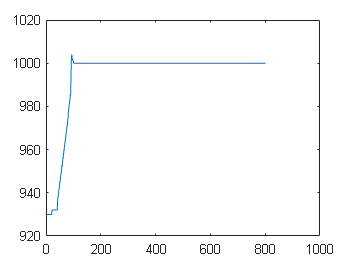

figure Name checking; plot(ca_phase_rec);

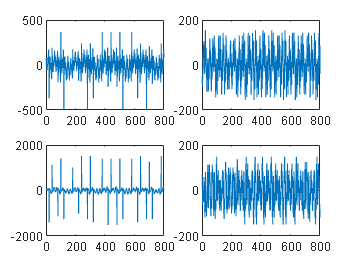

figure Name correlators;
subplot(2,2,1);
plot(IE);
subplot(2,2,2);
plot(QE);
subplot(2,2,3);
plot(IL);
subplot(2,2,4);
plot(QL);

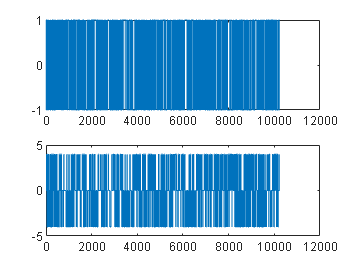

figure; subplot(2,1,1); plot(gc_p);
subplot(2,1,2); plot(I(end-10230:end));

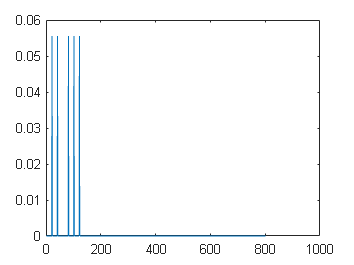

figure; plot(filter_in);

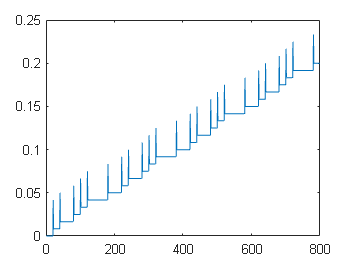

figure Name filter; plot(filter_out)

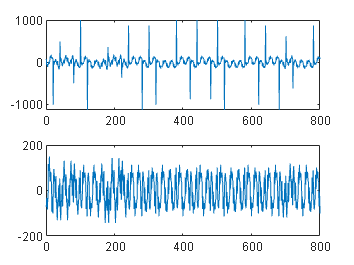

figure Name correlator;
subplot(2,1,1);
plot(IP);
subplot(2,1,2);
plot(QP);